## RRT

% parking lot costmap generation for real world parking lot
parking_spot = 4;
road_file_path = 'ParkingLotGeneration/ParkingLines/polylines9.shp';
parking_points_file_path = 'ParkingLotGeneration/ParkingSpots/points6.shp';
car_width  = 0.000005;
car_length = 0.00002;
road_f = shaperead(road_file_path);
points_f = shaperead(parking_points_file_path);
info = shapeinfo(road_file_path);
boundary_bounds = info.BoundingBox;
min_col = boundary_bounds(1, 1);
min_row = boundary_bounds(1, 2);
max_col = boundary_bounds(2, 1);
max_row = boundary_bounds(2, 2);
costmap = parking.generateCostMap(road_f, max_row, min_row, max_col, min_col);
% cost_map = vehicleCostmap(costmap);

Currently, this rrt algorithm does not generate equidistant path segments, if it is needed, we can modify the random method.

I'm also not using vehicleCostmap object anymore because I was having some problem with it. 

startPos = int64([0,0,0]); %x,y,theta (radians)
goalPoses = {[100,100,pi/4]};
minTurning = 10; %in meters
iterations = 2000;

% Matlab parking valet inputs
ws = load('input_variables_from_matlab_parking_example.mat');
startPos = ws.currentPose;
costmap = ws.combinedMap;
minTurning = 4;
routePlan = ws.routePlan;
goalPoses = num2cell(routePlan.EndPose, 2);
iterations = 2000;

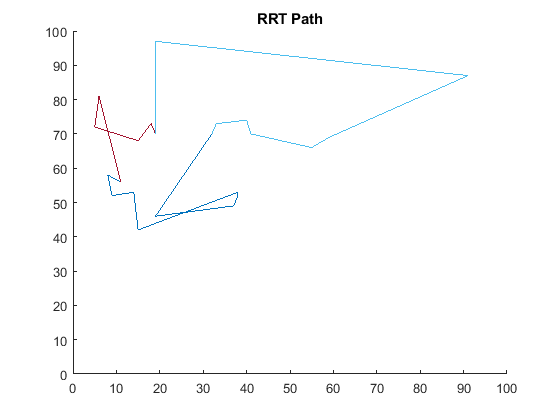

figure
hold on
for i = 1:length(goalPoses)
    tree = rrt(costmap, iterations, startPos, goalPoses{i}, minTurning);
    [path, Tree]= run(tree);
%     %if path is empty (i.e. did not find a path in last run), run again
%     %will fix this later
%     for i = 1: length(path)
%         disp(path{i});
%     end
    [X1, Y1, ~] = convert_cell_vector_to_double_vectors(path);
    plot(Y1, X1);
    startPos = goalPoses{i};
end
title('RRT Path')
hold off

[X, Y, Theta] = convert_cell_vector_to_double_vectors(tree.nodes);
figure
plot(Y, X, 'b.')
title('Points explored by RRT')

G = graph(tree.s, tree.t, tree.weight);
plot(G);
title('RRT Graph')

[X1, Y1, Theta1] = convert_cell_vector_to_double_vectors(path);
figure
plot(Y1, X1)
title('RRT Path')

%% Processing for plotting, should we just change the data structure itself
% this way?? Open Question...

function [X, Y, Theta] = convert_cell_vector_to_double_vectors(data)
    size = length(data);
    X = zeros(size);
    Y = zeros(size);
    Theta = zeros(size);
    for i = 1:size
        n = data{i};
        X(i) = n(1);
        Y(i) = n(2);
        Theta(i) = n(3);
    end
end
%%reference link:
%https://github.com/Mayankm96/Motion-Planning-GUI/blob/master/GUI/RRTree/RRT.m
